addpath('/Users/albertocarlevaro/Documents/Albi/CNR/Counterfactual/MultiCounterfactual/Datasets/');
addpath('/Users/albertocarlevaro/Documents/Albi/CNR/Counterfactual/MultiCounterfactual/MultiFiFa/MODEL')
addpath('/Users/albertocarlevaro/Documents/Albi/CNR/Counterfactual/MultiCounterfactual')

## CLEAN counterfactuals

folder_path='/Users/albertocarlevaro/Documents/Albi/CNR/Counterfactual/MultiCounterfactual/MultiStars/Counterfactuals'

folder_path = '/Users/albertocarlevaro/Documents/Albi/CNR/Counterfactual/MultiCounterfactual/MultiStars/Counterfactuals'

Num_classes=3;

disp('--Factual class -> 1--')

--Factual class -> 1--


counterfactuals1=load(fullfile(folder_path,"counterfactuals1.mat"));
counterfactuals_cleaned1 = clean_counterfactuals(counterfactuals1.counterfactuals1, Num_classes);

0/586 NOT AVAILABLE for column 2
0/586 NOT AVAILABLE for column 3


disp('--Factual class -> 2--')

--Factual class -> 2--


counterfactuals2=load(fullfile(folder_path,"counterfactuals2.mat"));
counterfactuals_cleaned2 = clean_counterfactuals(counterfactuals2.counterfactuals2, Num_classes);

0/591 NOT AVAILABLE for column 2
0/591 NOT AVAILABLE for column 3


disp('--Factual class -> 3--')

--Factual class -> 3--


counterfactuals3=load(fullfile(folder_path,"counterfactuals3.mat"));
counterfactuals_cleaned3 = clean_counterfactuals(counterfactuals3.counterfactuals3, Num_classes);

0/584 NOT AVAILABLE for column 2
0/584 NOT AVAILABLE for column 3


data1 = counterfactuals1.counterfactuals1;

% matrices of factuals and counterfactuals of class MF

F1_class = data1(:,1);
F1 = [];

for i = 1:size(F1_class,1)
    
    F1 = [F1;cell2mat(F1_class{i}(2,:)) ];

end

C12_class = data1(:,2);
C12 = [];

for i = 1:size(F1_class,1)
    
    C12 = [C12;cell2mat(C12_class{i}(2,:)) ];

end

C13_class = data1(:,3);
C13 = [];

for i = 1:size(F1_class,1)
    
    C13 = [C13;cell2mat(C13_class{i}(2,:)) ];

end
% mean of factuals and counterfactuals of class MF

mu_F1 = mean(F1,1);
mu_C12 = mean(C12,1);
mu_C13 = mean(C13,1);


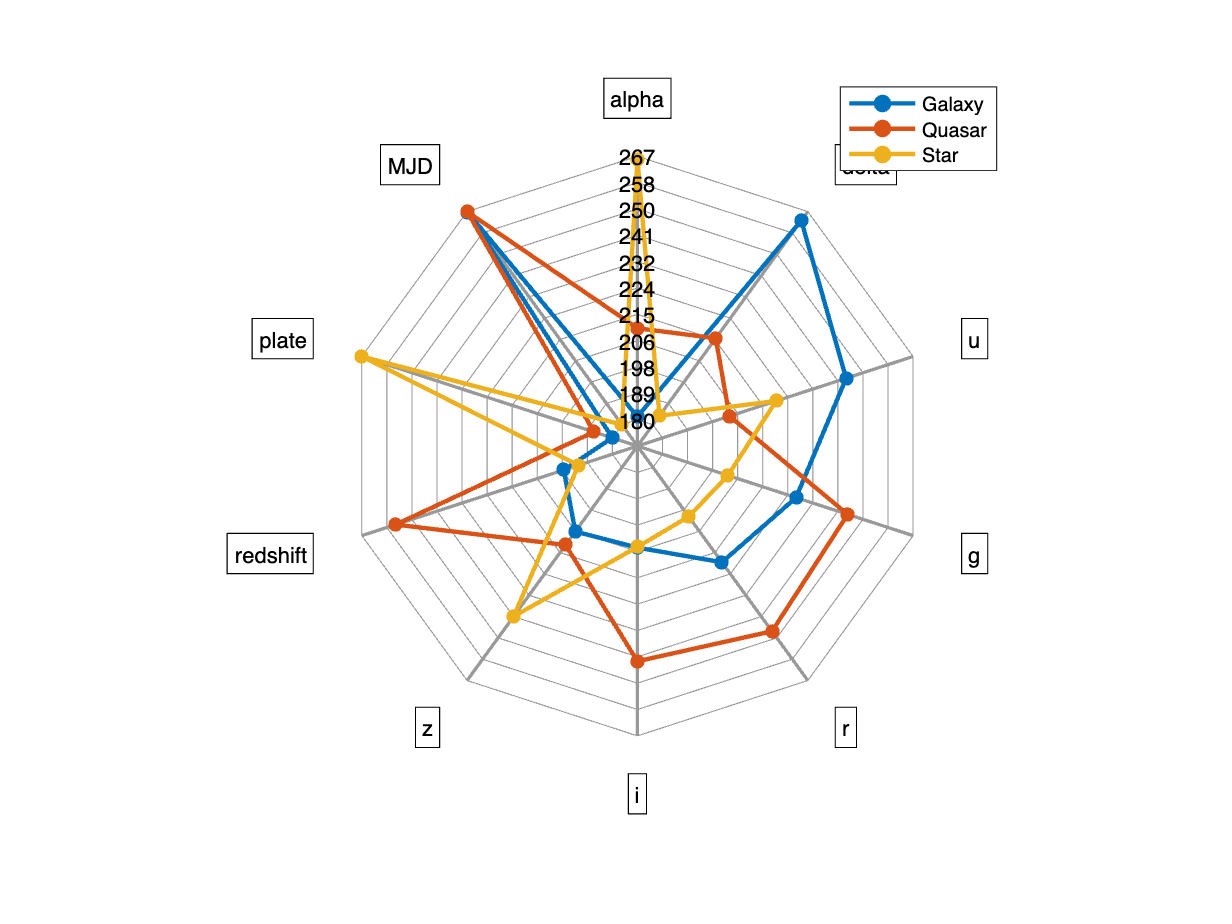

% Mental attributes

mu_F1 = mu_F1(:,1:10);
mu_C12 = mu_C12(:,1:10);
mu_C13 = mu_C13(:,1:10);


Min_Val = min([mu_F1; mu_C12; mu_C13])-1;
Max_Val = max([mu_F1; mu_C12; mu_C13])+1;

P = [mu_F1;mu_C12;mu_C13];

if exist('s', 'var') % Delete variable in workspace if exists
    delete(s);
end

figure(1)

s = spider_plot_class(P); % Spider plot

s.LegendLabels = {'Galaxy', 'Quasar', 'Star'};
s.LineStyle = {'-', '-', '-'};
s.AxesLabels = {'alpha', 'delta', 'u', 'g', 'r', 'i', 'z','redshift','plate','MJD'};
s.AxesInterval = 10;
s.AxesPrecision = 0;
s.LineWidth=[2, 2, 2];
%s.FillOption = {'on', 'on', 'on', 'on'};
%s.FillTransparency = [0.1, 0.1, 0.1, 0.1];
s.AxesLimits = [Min_Val; Max_Val];
s.AxesDisplay= 'one';

%s.AxesDisplay= 'data';
%title('Mental attributes');
